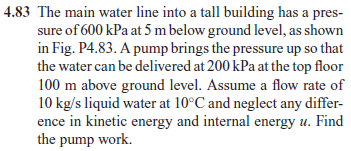

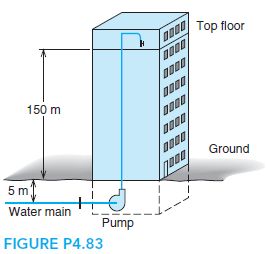

# symbolic units class

u = symunit;
g = 9.81*u.m/u.s^2;

# state 1 (saturated liquid water)

% --------------
% given
mdot1 = 10*u.kg/u.s;
p1 = 600*u.kPa;
T1 = 10*u.Celsius;
z1 = 0;
% --------------
% specific enthalpy
v1 = 0.001000*u.m^3/u.kg;
% --------------

# state 2 (saturated liquid water)

% --------------
% given
mdot2 = 10*u.kg/u.s;
p2 = 200*u.kPa;
T2 = 10*u.Celsius;
z2 = 105*u.m;
% --------------
% specific enthalpy
v2 = 0.001000*u.m^3/u.kg;
% --------------

# conservation of energy

Wdot = sym('Wdot');
Wdot = rewrite(solve(mdot1*(p1*v1+g*z1) == mdot2*(p2*v2+g*z2)+Wdot), u.kW);
Wdot_vpa = vpa(Wdot) %#ok

$$Wdot\_vpa = -6.3005\,\mathrm{kW}$$

clear Wdot_vpa;